# Create and Explore Datastore for Image Classification 

This example shows how to create, read, and augment an image datastore for use in training a deep learning network. In particular, this example shows how to create an `ImageDatastore` object from a collection of images, read and extract the properties of the datastore, and create an `augmentedImageDatastore` for use during training.

## Create Image Datastore

Use an [`imageDatastore`](docid:matlab_ref#butueui-1) object to manage a large collection of images that cannot altogether fit in memory. Large collections of images are common in deep learning applications, which regularly involve training on thousands of labeled images. These images are often stored in a folder, with subfolders containing images for each class.

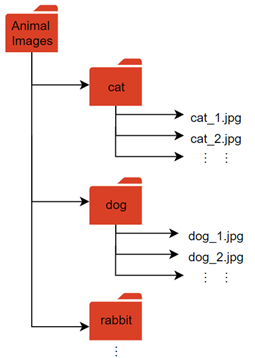

### Download Data

Download and extract an image classification data set.

The Example Food Images data set contains photographs of food in nine classes (*caeser_salad*, *caprese_salad*, *french_fries*, *greek_salad*, *hamburger*, *hot_dog*, *pizza*, *sashimi*, and *sushi*).

Download and extract the Example Food Images data set from [https://www.mathworks.com/supportfiles/nnet/data/ExampleFoodImageDataset.zip](https://www.mathworks.com/supportfiles/nnet/data/ExampleFoodImageDataset.zip). This data set is about 77 MB. Depending on your internet connection, the download process can take some time. Set `downloadFolder` to the location of the data.

url = "https://www.mathworks.com/supportfiles/nnet/data/ExampleFoodImageDataset.zip";
downloadFolder = tempdir;
filename = fullfile(downloadFolder,'ExampleFoodImageDataset.zip');

dataFolder = fullfile(downloadFolder, "ExampleFoodImageDataset");
if ~exist(dataFolder, "dir")
    fprintf("Downloading Example Food Image data set (77 MB)... ")
    websave(filename,url);
    unzip(filename,dataFolder);
    fprintf("Done.\n")
end

The images in this data set are separated into subfolders for each class.

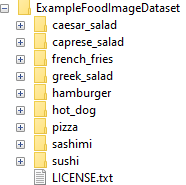

Create an image datastore from the images in the path and their subfolders. Use the folder names as label names.

foodImds = imageDatastore(dataFolder, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

## Properties of Datastore

Extract the properties of the datastore.

Find the total number of observations. This data set has 978 observations split into nine classes.

numObs = length(foodImds.Labels)

Find the number of observations per class. You can see that this data set does not contain an equal number of observations in each class.

numObsPerClass = countEachLabel(foodImds)

You can also visualize the distribution of the class labels using a histogram.

histogram(foodImds.Labels)
set(gca,'TickLabelInterpreter','none')

## Explore Datastore

Check that the data is as expected by viewing a random selection of images from the datastore.

numObsToShow = 8;
idx = randperm(numObs,numObsToShow);
imshow(imtile(foodImds.Files(idx),'GridSize',[2 4],'ThumbnailSize',[100 100]))

You can also view images that belong to a specific class.

class = "pizza";
idxClass = find(foodImds.Labels == class);
idx = randsample(idxClass,numObsToShow);
imshow(imtile(foodImds.Files(idx),'GridSize',[2 4],'ThumbnailSize',[100 100]));

To take a closer look at individual images in your datastore or folder, use the [Image Browser](docid:images_ref#bvcuqa4-1) app.

## Image Augmentation

Augmentation enables you to train networks to be invariant to distortions in image data. For example, you can add randomized rotations to input images so that a network is invariant to the presence of rotation. An [`augmentedImageDatastore`](docid:nnet_ref#mw_fd462475-1bc2-4f76-968c-c75721e5195f) object provides a convenient way to apply a limited set of augmentations to 2-D images for classification problems.

Define an augmentation scheme. This scheme applies a random rotation between [–90,90] degrees and a random scaling between [1,2]. The augmented datastore automatically resizes the images to the `inputSize` value during training.

imageAugmenter = imageDataAugmenter( ...
    'RandRotation',[-90 90], ...
    'RandScale',[1 2]);

inputSize = [100 100]; 

Using the augmentation scheme, define the augmented image datastore.

augFoodImds = augmentedImageDatastore(inputSize,foodImds, ...
    'DataAugmentation',imageAugmenter);

The augmented datastore contains the same number of images as the original image datastore.

augFoodImds.NumObservations

When you use an augmented image datastore as a source of training images, the datastore randomly perturbs the training data for each epoch, where an epoch is a full pass of the training algorithm over the entire training data set. Therefore, each epoch uses a slightly different data set, but the actual number of training images in each epoch does not change.

### Visualize Augmented Data

Visualize the augmented image data that you want to use to train the network.

Shuffle the datastore. 

augFoodImds = shuffle(augFoodImds);

The `augmentedImageDatastore` object applies the transformations when reading the datastore and does not store the transformed images in memory. Consequently, each time you read the same images, you see a random combination of the augmentations defined.

Use the [`read`](docid:matlab_ref#mw_a863c1c4-181c-4887-a7e9-36c15aea0376) function to read a subset of the augmented datastore.

subset1 = read(augFoodImds);

Reset the datastore to its state before calling read and read a subset of the datastore again.

reset(augFoodImds)
subset2 = read(augFoodImds);

Display the two subsets of the augmented images.

imshow(imtile(subset1.input,'GridSize',[2 4]))
imshow(imtile(subset2.input,'GridSize',[2 4]))

You can see that both instances show the same images with different transformations. Applying transformations to images is useful in deep learning applications, as you can train the network on randomly altered versions of an image. Doing so exposes the network to different variations of images from that class and enables it to learn to classify images even if they have different visual properties.

After creating your datastore object, use the [Deep Network Designer](docid:nnet_ref#mw_301a3a9d-998a-4668-aec4-f94646b76921) app or [`trainNetwork`](docid:nnet_ref#bu6sn4c) function to train an image classification network. For an example, see [Transfer Learning Using Pretrained Network](docid:nnet_ug#mw_a3c168e2-6934-4688-9d0b-4b2530adafa9).

For more information on preprocessing images for deep learning applications, see [Preprocess Images for Deep Learning](docid:nnet_ug#mw_347252a8-df98-46cd-8aa8-42fdf9619d24). You can also apply more advanced augmentations, such as varying levels of brightness or saturation, by using the [`transform`](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) and [`combine`](docid:matlab_ref#mw_b02645f0-b121-4bee-a5c0-1c669ce05793) functions. For more information, see [Datastores for Deep Learning](docid:nnet_ug#mw_225e8664-dc61-4a1a-a4bd-282396d33435).

*Copyright 2020 The MathWorks, Inc.*